# Frequency calculation

There are two ? marks in the calculation 

## Fw=sum(?.*exp(-j*?*t_vector))*t_step;

Change them to correct code and run the section


clear
load for_ps3.mat
t_step= t_vector(2) - t_vector(1)

t_step = 1.2207e-04


Fw_vector=[];
w_vector=[];

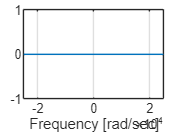


% wir lassen w von -25000 bis 25000 mit 50er schritten gehen.
for w=-25000:50:25000 

    % Das ist an sich eine Fourier Transformation nur das das integral
    % durch eine Riemann summe ausgetauscht wurde/approximiert wird. Die
    % rectpuls funktion agiert hier als ein Ersatz für den dirac Impuls der
    % nur Mathematisch existiert. Die breite des rectpuls entscheidet über 
    % die genauig keit der Fourier Transformation.
    Fw=sum(rectpuls(t_vector, 0.025).*exp(-1i*w*t_vector))*t_step;
    
    %Die Werte werden gespeichert damit sie nach dem For loop geplottet
    %werden können.
    w_vector=[w_vector w];
    Fw_vector=[Fw_vector Fw];
    
end
plot(w_vector,abs(Fw_vector))
xlabel('Frequency [rad/sec]')
grid